# Risposta dei sistemi lineari

## Setup

close all;
clear all;
clc;

## Variabili simboliche

syms G(s)
syms Y Yel

syms u(t)
syms y yel

## Definizione del problema

A = [
-2,     1,      0;
-1,     -2,     0;
0,      0,      -1;
]

A =     -2     1     0
    -1    -2     0
     0     0    -1


B = [0 1 0]'

B =      0
     1
     0


C = [0 1 0]

C =      0     1     0


D = 0

D = 0

u(t) = 1 * heaviside(t)

$$u(t) = \mathrm{heaviside}\left(t\right)$$

## Creazione del modello

### Funzione di trasferimento

G(s) = transfer_function(A,B,C,D);
pretty(G)

    s + 2
------------
 2
s  + 4 s + 5



### Trasformata dell'ingresso

U(s) = laplace(u(t));
pretty(U)

1
-
s



### Trasformata dell'uscita

Y(s) = G(s) * U(s);
pretty(Y)

      s + 2
----------------
    2
s (s  + 4 s + 5)



### Risposta nel dominio del tempo

y(t) = ilaplace(Y(s));
pretty(vpa(y))

0.4 - exp(-2.0 t) (cos(t) - 0.5 sin(t)) 0.4



### Evoluzione libera

Yel(s) = free_evolution(A,C,[1 0 0]');
pretty(Yel)

        1
- ------------
   2
  s  + 4 s + 5



yel(t) = ilaplace(Yel);
pretty(yel)

-exp(-2 t) sin(t)



## Grafici

% Definire l'asse temporale
tt = linspace(0, 4.5, 1000);

### Evoluzione libera

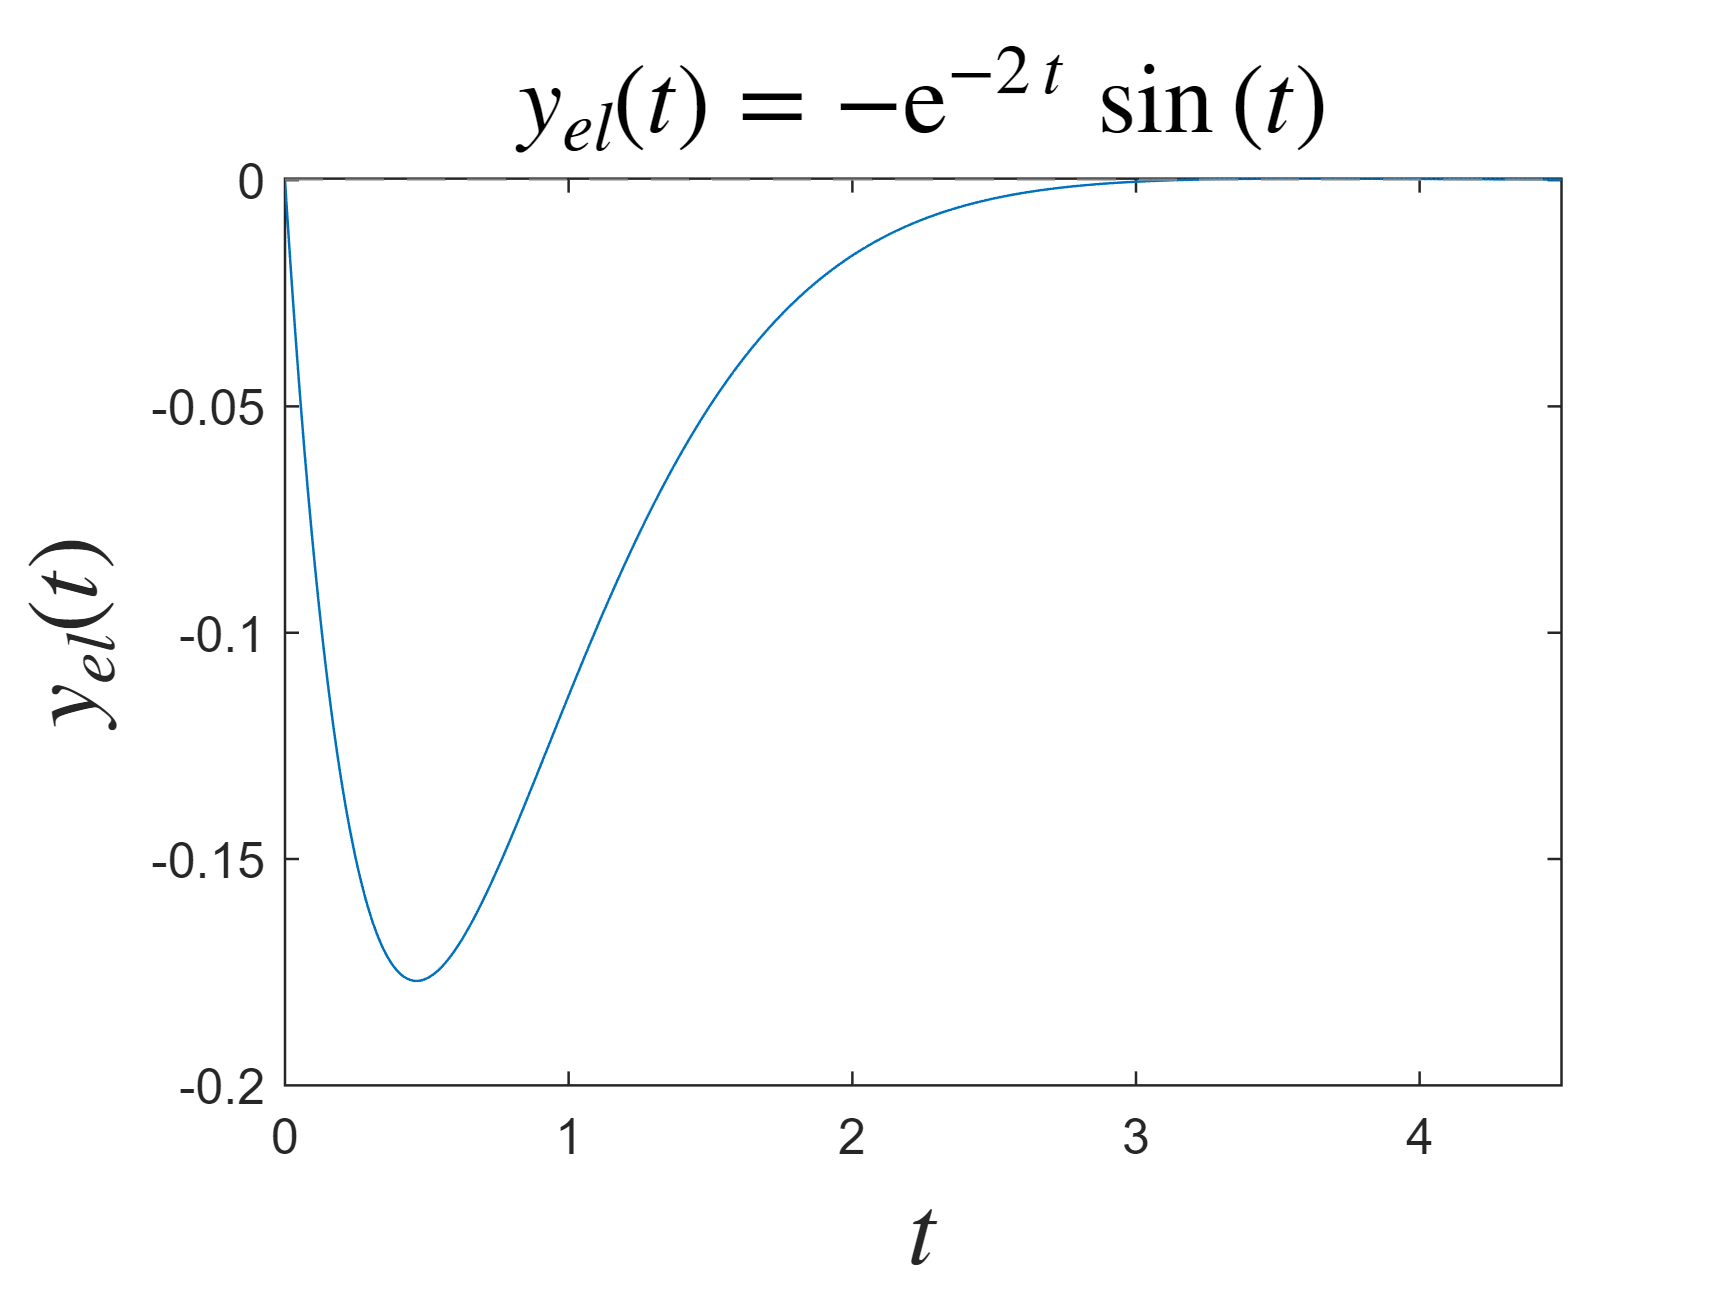

figure('Name','Evoluzione libera')
plot(tt, yel(tt))
xlim([tt(1) tt(end)])
xlabel('$$t$$', 'interpreter','latex', 'FontSize',20)
ylabel('$$y_{el}(t)$$', 'Interpreter','latex', 'FontSize',20)
yline(double(yel(tt(end))), '--', 'LineWidth',0.5, 'Color',[0.6 0.6 0.6])
title(['$$y_{el}(t) = ' latex(yel) '$$'], 'Interpreter','latex', 'FontSize',20)

### Evoluzione forzata

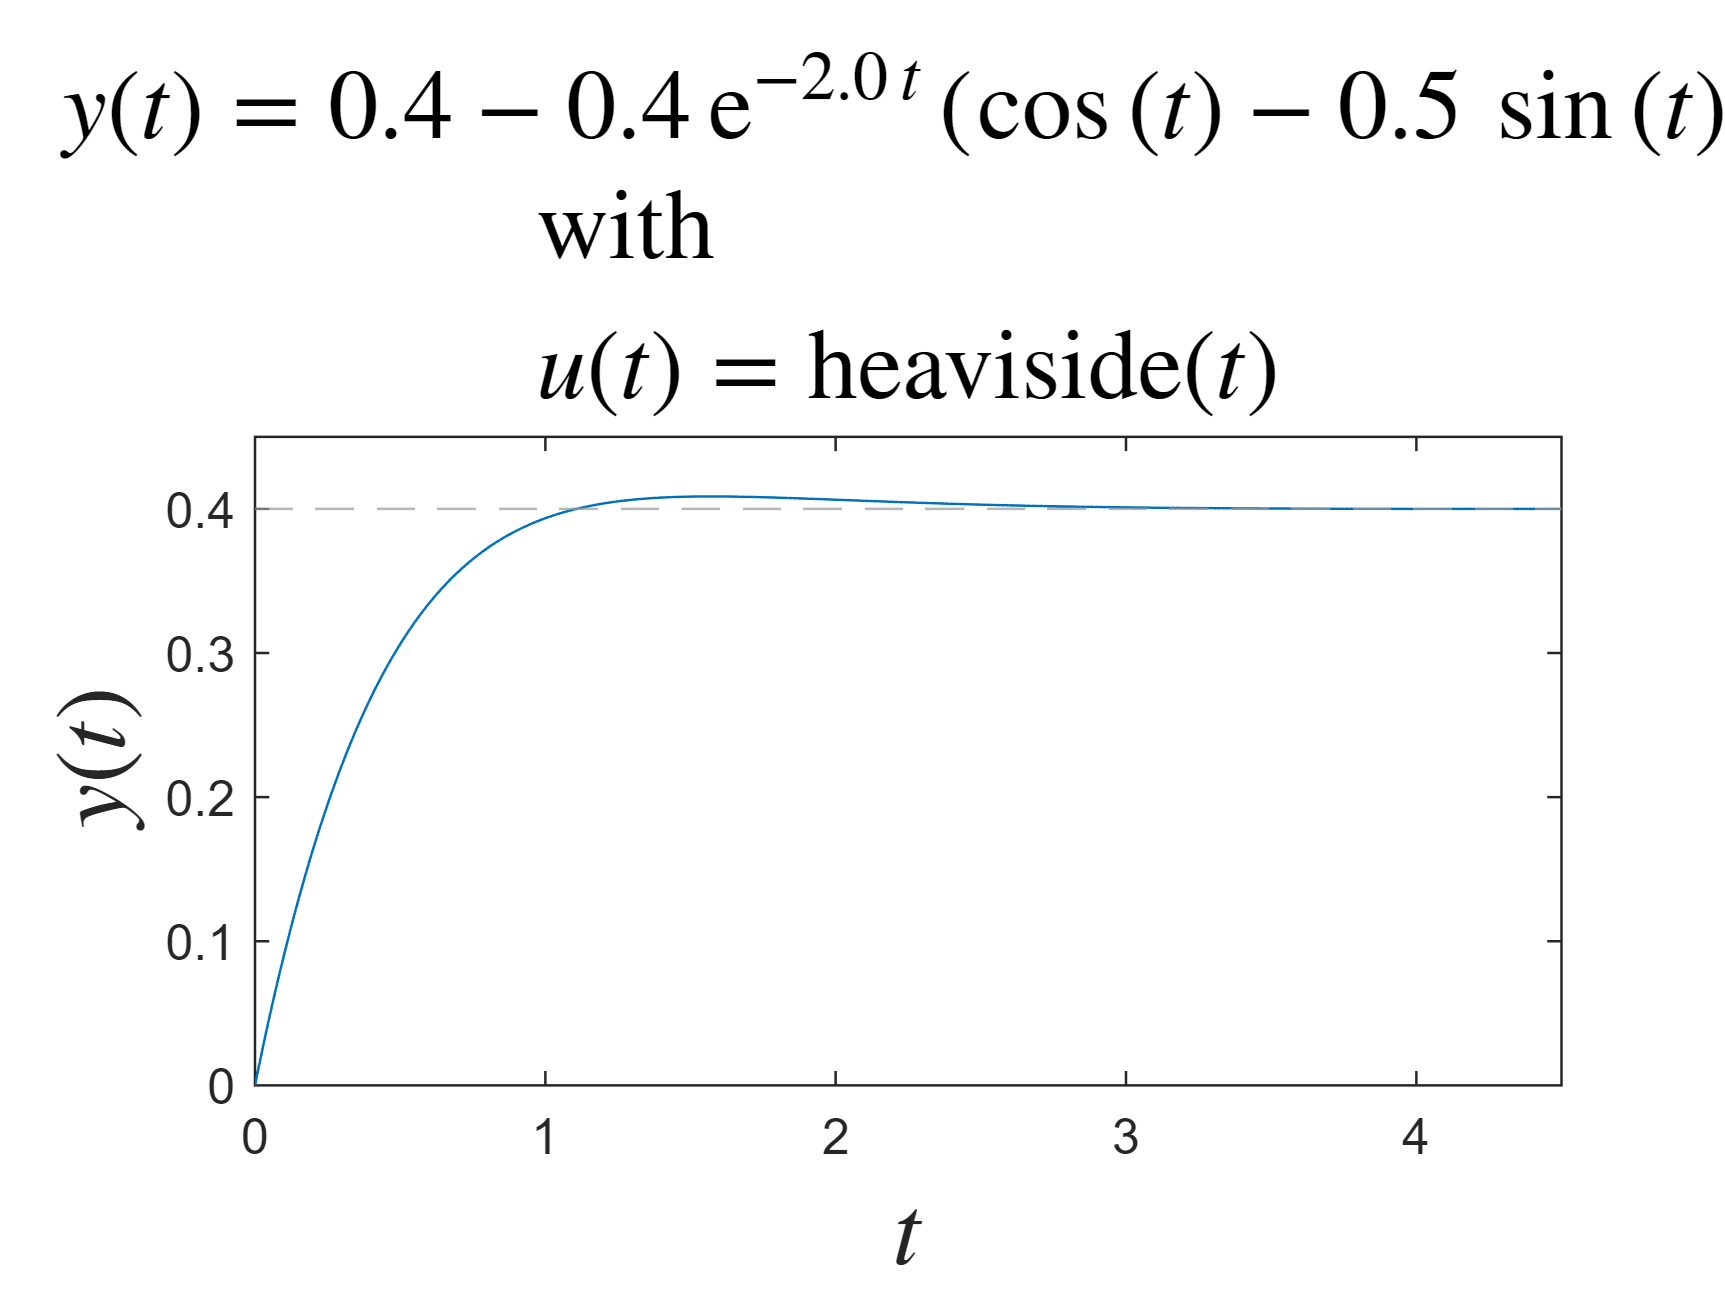

figure('Name','Evoluzione forzata')
plot(tt, y(tt));
xlim([tt(1) tt(end)])
xlabel('$$t$$', 'interpreter','latex', 'FontSize',20)
ylabel('$$y(t)$$', 'Interpreter','latex', 'FontSize',20)
yline(double(y(tt(end))), '--', 'LineWidth',0.5, 'Color',[0.6 0.6 0.6])
title({['$$y(t) = ' latex(vpa(y)) '$$'], ['with $$u(t) = ' latex(u) '$$']}, ...
    'Interpreter','latex', 'FontSize',20)

## Alternativa

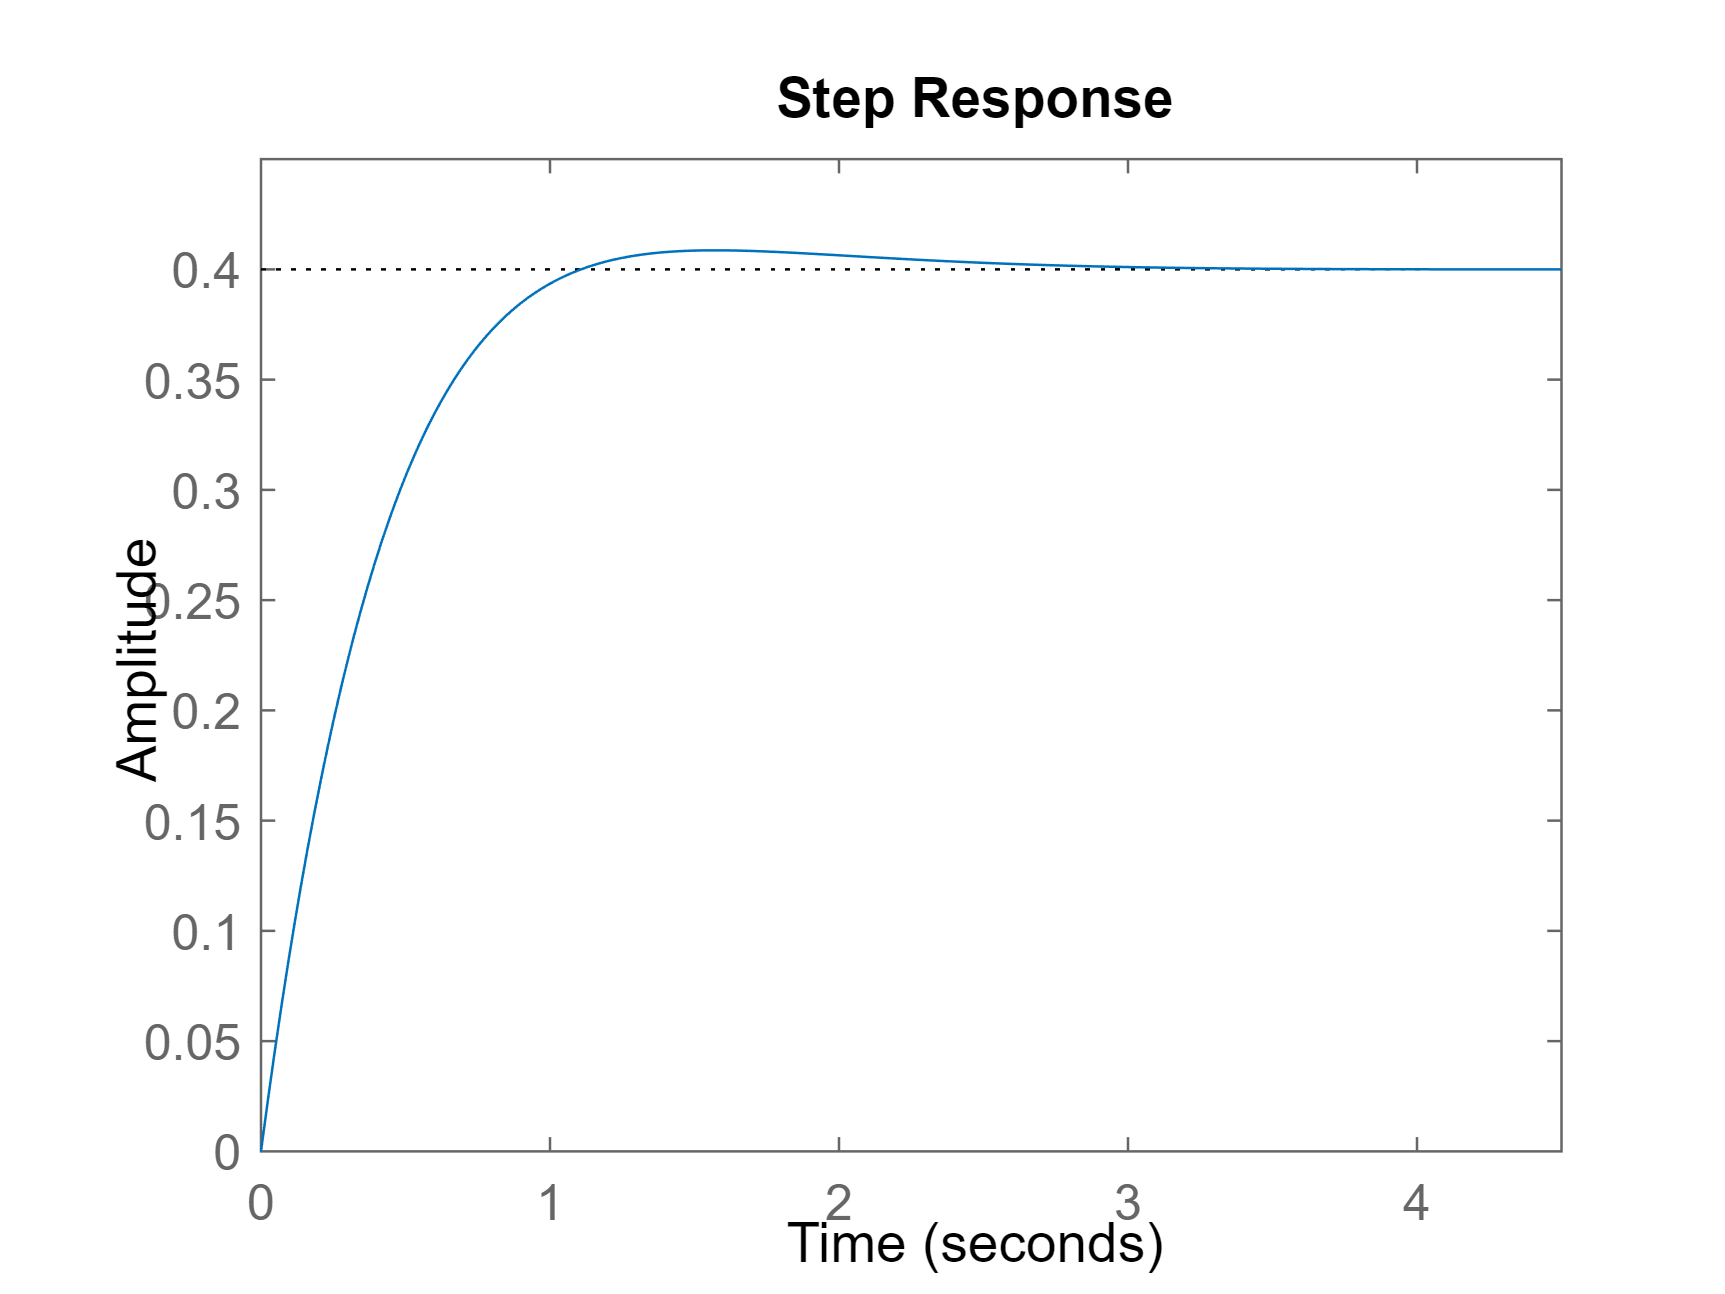

% Crea una figura
figure;

% Definisce il sistema di equazioni dello spazio di stato
state_space_model = ss(A, B, C, D);

% Definisce la fdt del modello
sys = tf(state_space_model);

% Calcola la riposta al gradino del sistema
step(sys);